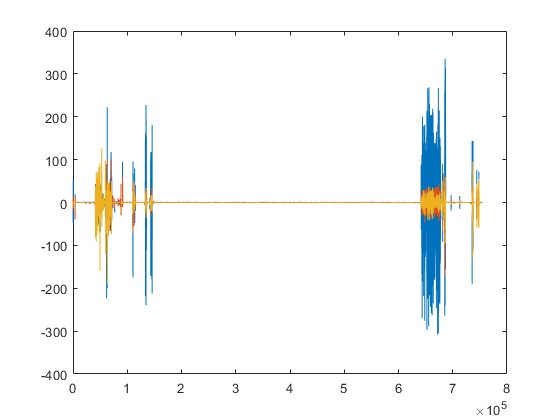

clear all;
%gain=0
mo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\log481.csv'); 
%gain=5
% mo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\log097.csv');

moo=mo;

mo=moo(:,[1:22]);  %%%%%%%%%%%%power_sensor%%%%%%%%%%%%%%%

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,2:4);  %無校正
gyr=mo(:,5:7);
m = mo(:,14:16); %%%% to guess
m2 = mo(:,17:19); %%%%
ax=acc1(:,1);ay=acc1(:,2);az=acc1(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
aG=sqrt(ax.^2+ay.^2+az.^2);
GG=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2)*0.01;
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

% m(:,1)=m(:,1)*0.805;
% m(:,2)=m(:,2)*0.805;
% m(:,3)=m(:,3)*1.468;

% m(:,1)=m(:,1)*0.751;
% m(:,2)=m(:,2)*0.751;
% m(:,3)=m(:,3)*1.210;

m(:,1)=m(:,1);
m(:,2)=m(:,2);
m(:,3)=m(:,3);

figure(1)
plot(m)

figure(2)
plot(m2)

std(mo(1:2000,:))'

ans =     5.7555
    0.0550
    0.0629
    0.0543
    0.0534
    0.0607
    0.0461
    3.0226
    0.9490
    0.7422


max(m)

ans =   335.1449  100.9600  126.5534


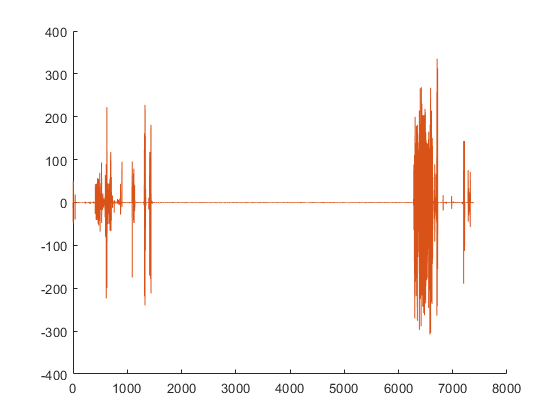


figure(3)
hold on
plot(t,m(:,1))
plot(t,m2(:,1))
hold off

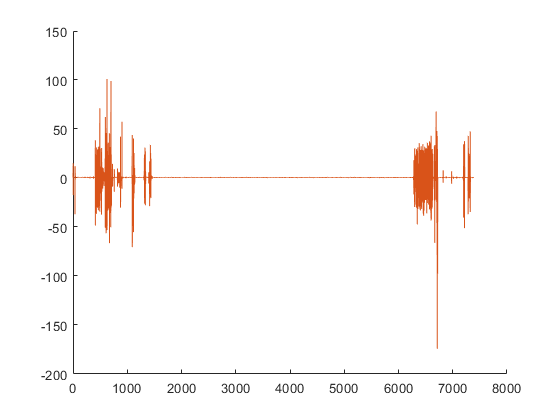

figure(4)
hold on
plot(t,m(:,2))
plot(t,m2(:,2))
hold off

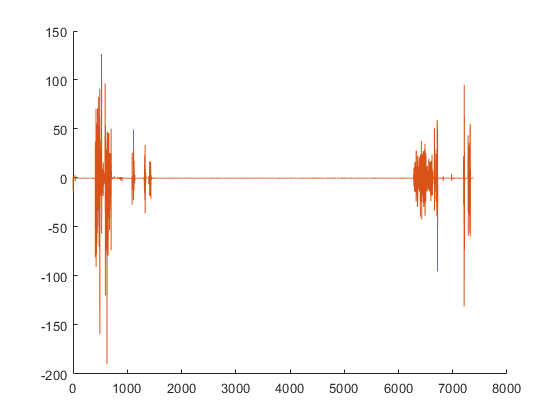

figure(5)
hold on
plot(t,m(:,3))
plot(t,m2(:,3))
hold off

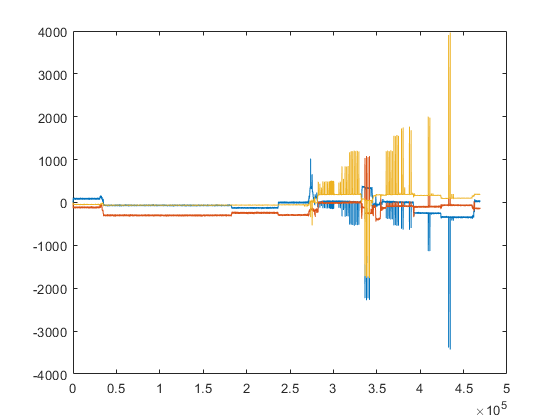

clear all;
%gain=0
% mo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\log099.csv'); 
%gain=7
% mo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\log097.csv');

mo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\log101.csv');
% mo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\log097.csv');

moo=mo;

mo=moo(:,[1:10]);  %%%%%%%%%%%%power_sensor%%%%%%%%%%%%%%%

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,2:4);  %無校正
gyr=mo(:,5:7);
m = mo(:,8:10); %%%% to guess
m2 = m; %%%%
ax=acc1(:,1);ay=acc1(:,2);az=acc1(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
aG=sqrt(ax.^2+ay.^2+az.^2);
GG=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2)*0.01;
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

% m(:,1)=m(:,1)*0.161;
% m(:,2)=m(:,2)*0.161;
% m(:,3)=m(:,3)*0.294;

% m(:,1)=m(:,1)*0.150;
% m(:,2)=m(:,2)*0.150;
% m(:,3)=m(:,3)*0.242;

m(:,1)=m(:,1);
m(:,2)=m(:,2);
m(:,3)=m(:,3);

plot(m)

std(mo(1:2000,:))'

ans =          0
    0.0077
    0.0074
    0.0102
    0.1360
    0.2237
    0.1140
    7.3342
    7.2957
    3.6011


max(m)

ans =         1024        1084        3964


%%power sensor testing

clear all;
close all;

%log120.csv
mo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\log120.csv');
% mo=load('C:\Users\sgrc-325\OneDrive - 國立成功大學 National Cheng Kung University\桌面\temp\log129.csv');

moo=mo;

mo=moo(:,[1:11]);  %%%%%%%%%%%%power_sensor%%%%%%%%%%%%%%%

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,2:4);  %無校正
gyr=mo(:,5:7);
m = mo(:,8:10); %%%% to guess
m2 = m; %%%%
ax=acc1(:,1);ay=acc1(:,2);az=acc1(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
aG=sqrt(ax.^2+ay.^2+az.^2);
GG=sqrt(gyr(:,1).^2+gyr(:,2).^2+gyr(:,3).^2)*0.01;
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

% m(:,1)=m(:,1)*0.161;
% m(:,2)=m(:,2)*0.161;
% m(:,3)=m(:,3)*0.294;

% m(:,1)=m(:,1)*0.150;
% m(:,2)=m(:,2)*0.150;
% m(:,3)=m(:,3)*0.242;

m(:,1)=m(:,1);
m(:,2)=m(:,2);
m(:,3)=m(:,3);
wireread=mo(:,11);

% plot(m)
std(mo(1:2000,:))'

ans =          0
    0.0032
    0.0036
    0.0053
    0.0908
    0.1128
    0.0851
    6.8179
    7.2230
    2.7844


max(m)

ans =         1042        1456         100


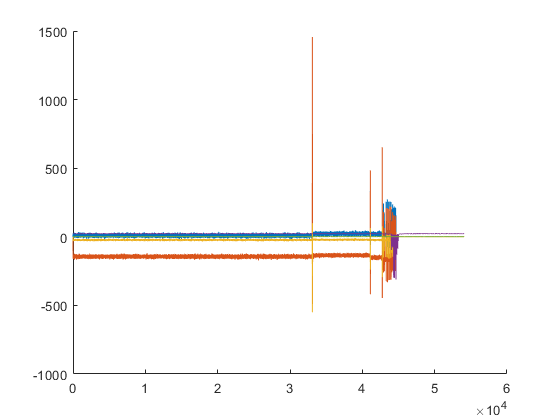

hold on
plot(m)
plot(wireread/10-1000)
plot(aG)
hold off